% 1. Load the data
data = readtable('C:\Users\yizha\qkd\FSOC\AO_simulation_log.csv')

data = 440×5 table
    timestep    E_power_sum    D_power_sum    num_airy    r0_ref
    ________    ___________    ___________    ________    ______

        0        9.118e+07      9.118e+07        2         0.01 
       20       9.5264e+07     3.1099e+08        2         0.01 
       40       9.8154e+07     3.0961e+08        2         0.01 
       60       9.6921e+07     3.0801e+08        2         0.01 
       80       9.3965e+07     3.0576e+08        2         0.01 
      100        9.273e+07     3.0488e+08        2         0.01 
      120       9.5062e+07     3.0324e+08        2         0.01 
      140       9.9722e+07     3.0264e+08        2         0.01 
      160       1.0467e+08      3.033e+08        2         0.01 
      180       1.0606e+08     3.0331e+08        2         0.01 
      200       1.1076e+08    


% Revert the data to true energy in Joules
scale_factor = 3.9e9;
true_E = data.E_power_sum / scale_factor;
true_D = data.D_power_sum / scale_factor;
%% 2. Time-Interval Aggregation (Row-Based)
interval_size = 780; % ms
time_jump = 20;      % ms
rows_per_interval = interval_size / time_jump; % Exactly 39 rows per cycle

num_rows = height(data); 

% Group into chunks of 39 rows (1-39 -> Group 1, 40-78 -> Group 2, etc.)
group_indices = floor((0:num_rows-1) / rows_per_interval)' + 1; 

% Calculate the mean energy for each 39-row interval
mean_E = accumarray(group_indices, true_E, [], @mean);
mean_D = accumarray(group_indices, true_D, [], @mean);

%% 3. Calculate AO Gain and Select 3 Specific Intervals
% Calculate the AO Gain (in dB) for every time interval
ao_gain_dB_all = 10 * log10(mean_D ./ mean_E);

% Sort the gains to find our three target atmospheric states
[sorted_gains, sorted_indices] = sort(ao_gain_dB_all);

min_idx = sorted_indices(1);
mid_idx = sorted_indices(round(length(sorted_indices)/2));
max_idx = sorted_indices(end);

target_intervals = [min_idx, mid_idx, max_idx];
interval_labels = {'Lowest AO Gain', 'Mid AO Gain', 'Highest AO Gain'};

fprintf('\nSelected Intervals:\n');


Selected Intervals:


fprintf('1. %s (Interval %d): %.2f dB Gain\n', interval_labels{1}, target_intervals(1), ao_gain_dB_all(target_intervals(1)));

1. Lowest AO Gain (Interval 11): 1.69 dB Gain


fprintf('2. %s (Interval %d): %.2f dB Gain\n', interval_labels{2}, target_intervals(2), ao_gain_dB_all(target_intervals(2)));

2. Mid AO Gain (Interval 7): 3.25 dB Gain


fprintf('3. %s (Interval %d): %.2f dB Gain\n', interval_labels{3}, target_intervals(3), ao_gain_dB_all(target_intervals(3)));

3. Highest AO Gain (Interval 2): 6.59 dB Gain


%% 4. Simulate Specific Intervals
schemes_to_run = {'OOK', 'BPSK', 'DPSK', 'QAM4'}; 
% We increase the bits per point since we are no longer aggregating 100+ intervals together
num_bits_per_sim = 1e5; 

% Clean X-Axis sweep for the Uncorrected Signal
snr_sweep_dB = -5:2:20; 

results = struct();

for s = 1:length(schemes_to_run)
    mod_scheme = schemes_to_run{s};
    fprintf('Simulating %s...\n', mod_scheme);
    
    for lvl = 1:3
        current_interval = target_intervals(lvl);
        current_gain = ao_gain_dB_all(current_interval);
        
        % Uncorrected SNR is the baseline. Corrected SNR is simply shifted by the Gain.
        snr_E_dB_array = snr_sweep_dB;
        snr_D_dB_array = snr_sweep_dB + current_gain;
        
        ber_E_sim = zeros(1, length(snr_sweep_dB));
        ber_D_sim = zeros(1, length(snr_sweep_dB));
        ber_E_theory = zeros(1, length(snr_sweep_dB));
        ber_D_theory = zeros(1, length(snr_sweep_dB));

        for i = 1:length(snr_sweep_dB)
            tx_bits_e = randi([0 1], num_bits_per_sim, 1);
            tx_bits_d = randi([0 1], num_bits_per_sim, 1);

            %% --- Modulation, Noise, and Demodulation ---
            switch mod_scheme
                case 'OOK'
                    rx_sig_e = awgn(tx_bits_e, snr_E_dB_array(i), 'measured'); 
                    rx_bits_e = rx_sig_e > 0.5;
                    rx_sig_d = awgn(tx_bits_d, snr_D_dB_array(i), 'measured'); 
                    rx_bits_d = rx_sig_d > 0.5;
                    
                case 'BPSK'
                    % Force symbols to be complex so AWGN splits noise between I and Q
                    tx_sym_e = complex(2*tx_bits_e - 1, 0);
                    tx_sym_d = complex(2*tx_bits_d - 1, 0);
                    
                    rx_sig_e = awgn(tx_sym_e, snr_E_dB_array(i), 'measured'); 
                    % We only evaluate the Real (In-phase) part for our decision
                    rx_bits_e = real(rx_sig_e) > 0; 
                    
                    rx_sig_d = awgn(tx_sym_d, snr_D_dB_array(i), 'measured'); 
                    rx_bits_d = real(rx_sig_d) > 0;
                    
                case 'DPSK'
                    tx_sym_e = dpskmod(tx_bits_e, 2);
                    tx_sym_d = dpskmod(tx_bits_d, 2);
                    rx_sig_e = awgn(tx_sym_e, snr_E_dB_array(i), 'measured'); 
                    rx_bits_e = dpskdemod(rx_sig_e, 2); 
                    rx_sig_d = awgn(tx_sym_d, snr_D_dB_array(i), 'measured'); 
                    rx_bits_d = dpskdemod(rx_sig_d, 2); 
                    
                case 'QAM4'
                    tx_sym_e = qammod(tx_bits_e, 4, 'InputType', 'bit', 'UnitAveragePower', true);
                    tx_sym_d = qammod(tx_bits_d, 4, 'InputType', 'bit', 'UnitAveragePower', true);
                    rx_sig_e = awgn(tx_sym_e, snr_E_dB_array(i), 'measured'); 
                    rx_bits_e = qamdemod(rx_sig_e, 4, 'OutputType', 'bit', 'UnitAveragePower', true); 
                    rx_sig_d = awgn(tx_sym_d, snr_D_dB_array(i), 'measured'); 
                    rx_bits_d = qamdemod(rx_sig_d, 4, 'OutputType', 'bit', 'UnitAveragePower', true); 
            end
            
            % Count Errors
            ber_E_sim(i) = sum(tx_bits_e ~= rx_bits_e) / num_bits_per_sim;
            ber_D_sim(i) = sum(tx_bits_d ~= rx_bits_d) / num_bits_per_sim;
        end
        
        %% --- Theoretical Average BER Calculation ---
        switch mod_scheme
            case 'OOK'
                ber_E_theory = 0.5 * erfc(0.5 * sqrt(10.^(snr_E_dB_array / 10)));
                ber_D_theory = 0.5 * erfc(0.5 * sqrt(10.^(snr_D_dB_array / 10)));
            case 'BPSK'
                ber_E_theory = 0.5 * erfc(sqrt(10.^(snr_E_dB_array / 10)));
                ber_D_theory = 0.5 * erfc(sqrt(10.^(snr_D_dB_array / 10)));
            case 'DPSK'
                ber_E_theory = 0.5 * exp(-10.^(snr_E_dB_array / 10));
                ber_D_theory = 0.5 * exp(-10.^(snr_D_dB_array / 10));
            case 'QAM4'
                ber_E_theory = 0.5 * erfc(sqrt(0.5 * 10.^(snr_E_dB_array / 10)));
                ber_D_theory = 0.5 * erfc(sqrt(0.5 * 10.^(snr_D_dB_array / 10)));
        end
        
        % Zero-Error Handling for Logarithmic Plotting
        is_zero_E = (ber_E_sim == 0);
        is_zero_D = (ber_D_sim == 0);
        ber_E_sim(is_zero_E) = ber_E_theory(is_zero_E);
        ber_D_sim(is_zero_D) = ber_D_theory(is_zero_D);
        
        % Save to Struct under Scheme AND Level
        level_name = sprintf('level_%d', lvl);
        results.(mod_scheme).(level_name).gain_dB = current_gain;
        results.(mod_scheme).(level_name).snr_E = snr_E_dB_array;
        results.(mod_scheme).(level_name).ber_E = ber_E_sim;
        results.(mod_scheme).(level_name).snr_D = snr_D_dB_array;
        results.(mod_scheme).(level_name).ber_D = ber_D_sim;
        results.(mod_scheme).(level_name).theory_E = ber_E_theory;
        results.(mod_scheme).(level_name).theory_D = ber_D_theory;
        results.(mod_scheme).(level_name).is_zero_E = is_zero_E;
        results.(mod_scheme).(level_name).is_zero_D = is_zero_D;
    end
end

Simulating OOK...
Simulating BPSK...
Simulating DPSK...
Simulating QAM4...


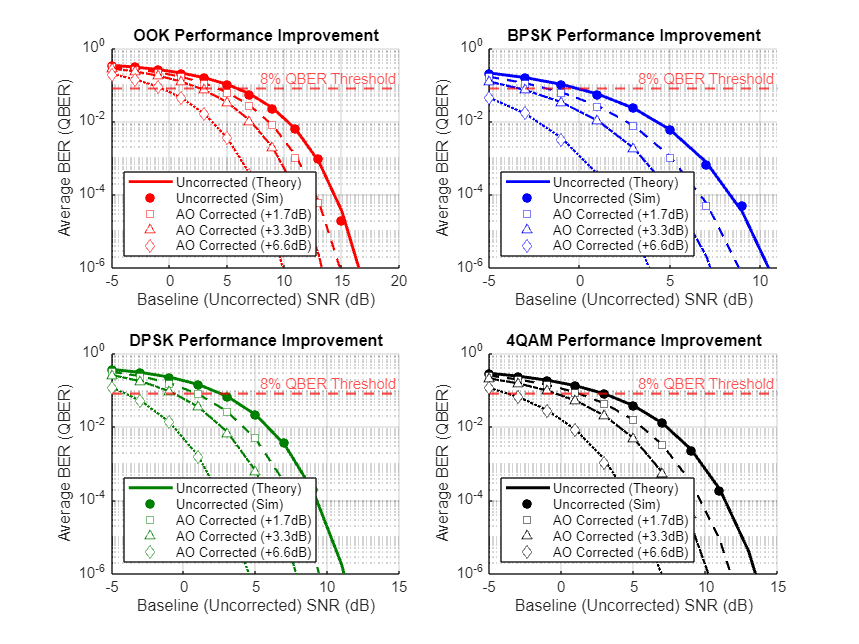

%% 5. Plot the Consolidated 2x2 Grid with QBER Threshold
figure('Position', [100, 100, 1200, 900]); 

% Using RGB triplets: Red, Blue, Dark Green, Black
color_map = containers.Map({'OOK', 'BPSK', 'DPSK', 'QAM4'}, ...
    {[1, 0, 0], [0, 0, 1], [0, 0.5, 0], [0, 0, 0]}); 

line_styles = {'-', '--', '-.', ':'};
markers = {'o', 's', '^', 'd'};

% QKD Security Threshold
qber_threshold = 0.08; 

for s = 1:length(schemes_to_run)
    mod_scheme = schemes_to_run{s};
    c = color_map(mod_scheme); % This is now an RGB array
    display_name = strrep(mod_scheme, 'QAM4', '4QAM');
    
    subplot(2, 2, s);
    hold on;
    
    % 1. Plot the UNCORRECTED baseline 
    data_base = results.(mod_scheme).level_1;
    mask_base = ~data_base.is_zero_E;
    
    % Plot uncorrected lines (Notice the updated 'Color' syntax)
    semilogy(data_base.snr_E, data_base.theory_E, '-', 'Color', c, 'LineWidth', 2, 'DisplayName', 'Uncorrected (Theory)');
    semilogy(data_base.snr_E(mask_base), data_base.ber_E(mask_base), 'o', 'Color', c, 'MarkerFaceColor', c, 'MarkerSize', 6, 'DisplayName', 'Uncorrected (Sim)');
    
    % 2. Plot the 3 CORRECTED levels against the BASELINE SNR
    for lvl = 1:3
        level_name = sprintf('level_%d', lvl);
        data = results.(mod_scheme).(level_name);
        mask_D = ~data.is_zero_D;
        
        gain_str = sprintf('AO Corrected (+%.1fdB)', data.gain_dB);
        
        semilogy(data.snr_E, data.theory_D, line_styles{lvl+1}, 'Color', c, 'LineWidth', 1.5, 'HandleVisibility', 'off'); 
        semilogy(data.snr_E(mask_D), data.ber_D(mask_D), markers{lvl+1}, 'Color', c, 'MarkerFaceColor', 'w', 'MarkerSize', 6, 'DisplayName', gain_str);
    end
    
    % 3. Add the QBER Security Threshold Line
    % We set HandleVisibility to 'off' so it doesn't clutter the legend
    yline(qber_threshold, '--r', '8% QBER Threshold', 'LineWidth', 1.5, 'LabelHorizontalAlignment', 'right', 'HandleVisibility', 'off');
    
    hold off;
    
    xlabel('Baseline (Uncorrected) SNR (dB)'); 
    ylabel('Average BER (QBER)');
    title(sprintf('%s Performance Improvement', display_name));
    grid on;
    set(gca, 'YScale', 'log', 'YLim', [1e-6 1]);
    
    legend('Location', 'southwest', 'FontSize', 9);
end

%% 6. Constellation Comparison Plots (Auto-Generate All AO Levels)

% Load the AO simulation log
ao_log_data = readtable('C:\Users\yizha\qkd\FSOC\AO_simulation_log.csv');

% Extract all unique r0 values
unique_r0s = unique(ao_log_data.r0_ref, 'stable');

% Calculate the minimum, median, and maximum r0 values
r0_min = min(unique_r0s);
r0_med = median(unique_r0s);
r0_max = max(unique_r0s);

% ---> SELECT WHICH r0 MATCHES YOUR CURRENT DATA HERE <---
r0_values = [inf
    ,r0_max,r0_med,r0_min]

Error using vertcat
Dimensions of arrays being concatenated are not consistent.


% Using the same RGB triplets for consistency
color_map = containers.Map({'OOK', 'BPSK', 'DPSK', 'QAM4'}, ...
    {[1, 0, 0], [0, 0, 1], [0, 0.5, 0], [0, 0, 0]}); 

% QKD Security Threshold
qber_threshold = 0.08; 

% Loop through 4 states: 0 = Uncorrected, 1 = Level 1, 2 = Level 2, 3 = Level 3
for ao_state = 0:3
    figure('Position', [150 + ao_state*50, 150 + ao_state*50, 800, 600]); 
    hold on;
    
    for s = 1:length(schemes_to_run)
        mod_scheme = schemes_to_run{s};
        c = color_map(mod_scheme); 
        display_name = strrep(mod_scheme, 'QAM4', '4QAM');
        
        if ao_state == 0
            % --- UNCORRECTED BASELINE ---
            data = results.(mod_scheme).level_1;
            mask = ~data.is_zero_E;
            
            % Plot Theory & Sim
            semilogy(data.snr_E, data.theory_E, '-', 'Color', c, 'LineWidth', 2, 'DisplayName', sprintf('%s (Theory)', display_name));
            semilogy(data.snr_E(mask), data.ber_E(mask), 'o', 'Color', c, 'MarkerFaceColor', c, 'MarkerSize', 6, 'DisplayName', sprintf('%s (Sim)', display_name));
            
            % Title dynamically uses the r0_value selected above
            title_str = sprintf('Modulation Comparison (Uncorrected Channel | r_0 = %.3f m)', r0_values(ao_state+1));
        else
            % --- AO CORRECTED LEVELS ---
            level_name = sprintf('level_%d', ao_state);
            data = results.(mod_scheme).(level_name);
            mask = ~data.is_zero_D;
            
            % Plot Theory & Sim
            semilogy(data.snr_E, data.theory_D, '-', 'Color', c, 'LineWidth', 2, 'DisplayName', sprintf('%s (Theory)', display_name));
            semilogy(data.snr_E(mask), data.ber_D(mask), 'o', 'Color', c, 'MarkerFaceColor', c, 'MarkerSize', 6, 'DisplayName', sprintf('%s (Sim)', display_name));
            
            % Title dynamically uses Gain and the r0_value selected above
            title_str = sprintf('Modulation Comparison (AO Level %d: +%.1fdB Gain | r_0 = %.3f m)', ao_state, data.gain_dB, r0_values(ao_state+1));
        end
    end
    
    % Add the QBER Security Threshold Line
    yline(qber_threshold, '--r', '8% QBER Threshold', 'LineWidth', 1.5, 'LabelHorizontalAlignment', 'left', 'HandleVisibility', 'off');
    
    hold off;
    
    % Formatting
    xlabel('Baseline (Uncorrected) SNR (dB)'); 
    ylabel('Average BER (QBER)');
    title(title_str);
    grid on;
    set(gca, 'YScale', 'log', 'YLim', [1e-6 1]);
    
    legend('Location', 'southwest', 'FontSize', 10);
end

%% 7. AO Efficiency Analysis (SNR Threshold for k Improvement)

% Define your targets
target_k = 2.5;         % Target improvement factor (Uncorrected BER / Corrected BER)
target_ao_level = 1;    % Choose which AO level to evaluate (1 = Low, 2 = Mid, 3 = High)

level_name = sprintf('level_%d', target_ao_level);

fprintf('\n--- AO Efficiency Analysis (Target k = %.1f) ---\n', target_k);
fprintf('Evaluating %s...\n\n', level_name);

for s = 1:length(schemes_to_run)
    mod_scheme = schemes_to_run{s};
    display_name = strrep(mod_scheme, 'QAM4', '4QAM');
    
    % Extract the theoretical data for this specific modulation and AO level
    data = results.(mod_scheme).(level_name);
    
    % Calculate the ratio K at every existing SNR point
    % K = Uncorrected BER / Corrected BER
    K_array = data.theory_E ./ data.theory_D;
    snr_array = data.snr_E;
    
    % Generate a high-resolution SNR grid (10,000 points) for precise threshold detection
    fine_snr = linspace(min(snr_array), max(snr_array), 10000);
    
    % Interpolate the K ratio across the fine grid using 'pchip' (shape-preserving)
    fine_K = interp1(snr_array, K_array, fine_snr, 'pchip');
    
    % Find the index of the first point where the K ratio hits or exceeds our target
    idx_threshold = find(fine_K >= target_k, 1);
    
    % Output the results
    if ~isempty(idx_threshold)
        snr_threshold = fine_snr(idx_threshold);
        fprintf('%s:\n', display_name);
        fprintf('  -> SNR Threshold: %5.2f dB \n', snr_threshold);
        fprintf('  -> Meaning: For any SNR > %.2f dB, AO makes BER at least %.1fx smaller.\n\n', snr_threshold, target_k);
    else
        fprintf('%s:\n', display_name);
        fprintf('  -> Target improvement of %.1fx never reached in this simulated SNR range.\n\n', target_k);
    end
end
fprintf('--------------------------------------------------\n');
%% 8. AO Efficiency Threshold Visualization (2x2 Grid)

% --- PREDETERMINED VALUES ---
target_k = 10;         % Target improvement factor (Uncorrected BER / Corrected BER)
target_ao_level = 3;    % Which AO level to evaluate (1 = Low, 2 = Mid, 3 = High)
% ----------------------------

level_name = sprintf('level_%d', target_ao_level);

% Create a new full-screen-ish figure for the 2x2 grid
figure('Position', [100, 100, 1000, 800], 'Name', sprintf('AO Efficiency Threshold (k=%.1f)', target_k));

for s = 1:length(schemes_to_run)
    mod_scheme = schemes_to_run{s};
    display_name = strrep(mod_scheme, 'QAM4', '4QAM');
    
    % Select subplot (2 rows, 2 columns, index s)
    subplot(2, 2, s);
    hold on;
    
    % Extract the data for this specific modulation and AO level
    data = results.(mod_scheme).(level_name);
    
    % --- 1. CALCULATE THE THRESHOLD ---
    % Calculate K ratio on a high-res grid to find the exact crossing point
    K_array = data.theory_E ./ data.theory_D;
    fine_snr = linspace(min(data.snr_E), max(data.snr_E), 10000);
    fine_K = interp1(data.snr_E, K_array, fine_snr, 'pchip');
    idx_threshold = find(fine_K >= target_k, 1);
    
    % --- 2. PLOT THE DATA ---
    % Uncorrected Data (Black, Solid, Filled Circles)
    mask_E = ~data.is_zero_E;
    p1 = semilogy(data.snr_E, data.theory_E, '-k', 'LineWidth', 1.5, 'DisplayName', 'Uncorrected (Theory)');
    p2 = semilogy(data.snr_E(mask_E), data.ber_E(mask_E), 'ok', 'MarkerFaceColor', 'k', 'MarkerSize', 6, 'DisplayName', 'Uncorrected (Sim)');
    
    % Corrected Data (Black, Dashed, Hollow Squares)
    mask_D = ~data.is_zero_D;
    p3 = semilogy(data.snr_E, data.theory_D, '--k', 'LineWidth', 1.5, 'DisplayName', sprintf('AO Level %d (Theory)', target_ao_level));
    p4 = semilogy(data.snr_E(mask_D), data.ber_D(mask_D), 'sk', 'MarkerSize', 7, 'DisplayName', sprintf('AO Level %d (Sim)', target_ao_level));
    
    % --- 3. PLOT THE THRESHOLD LINE ---
    if ~isempty(idx_threshold)
        snr_threshold = fine_snr(idx_threshold);
        
        % Draw the vertical red dashed line
        xline(snr_threshold, '--r', sprintf('%.1fx Improvement Threshold', target_k), ...
            'LineWidth', 1.5, 'LabelVerticalAlignment', 'bottom', ...
            'LabelHorizontalAlignment', 'left', 'HandleVisibility', 'off', 'FontSize', 9);
        
        % Optional: Add a red star exactly where the uncorrected curve hits the threshold
        % threshold_ber = interp1(data.snr_E, data.theory_E, snr_threshold, 'pchip');
        % plot(snr_threshold, threshold_ber, 'pr', 'MarkerFaceColor', 'r', 'MarkerSize', 10, 'HandleVisibility', 'off');
    else
        % If the threshold is never reached, just note it in the title
        title_suffix = ' (Target k Not Reached)';
    end
    
    % --- 4. FORMATTING ---
    hold off;
    grid on;
    set(gca, 'YScale', 'log', 'YLim', [1e-6 1], 'XLim', [min(data.snr_E) max(data.snr_E)]);
    
    xlabel('Baseline (Uncorrected) SNR (dB)');
    ylabel('Average BER');
    title(sprintf('%s Performance (Target k = %.1f)', display_name, target_k));
    
    % Only put the legend on the first subplot to keep it uncluttered
    if s == 1
        legend([p1, p2, p3, p4], 'Location', 'southwest', 'FontSize', 9);
    end
end

%% 6. Save Data to a Designated Path
% NOTE: Make sure to change this string to an actual folder on your PC!
save_path = 'C:\Users\yizha\OneDrive\Desktop\'; 
if ~exist(save_path, 'dir')
    mkdir(save_path);
end
file_name = fullfile(save_path, 'modulation_results.mat');
save(file_name, 'results');
fprintf('\nResults successfully saved to: %s\n', file_name);